# パラメータ化拡張GFTによるDiGraph辞書の学習

2024年4月29日

村松正吾，内藤翼（新潟大学）

#### 参考文献:

- H. Kitamura, H. Yasuda, Y. Tanaka and S. Muramatsu, "Realization of DiGraph Filters Via Augmented GFT," 2023 IEEE International Conference on Image Processing (ICIP), Kuala Lumpur, Malaysia, 2023, pp. 2885-2889, doi: 10.1109/ICIP49359.2023.10222618.

- Abstract: This study proposes a filtering method for directed graph (digraph) signals. In order to realize digraph filtering, a novel graph Fourier transform (GFT), – Augmented GFT (AuGFT) –, is proposed by defining an Hermitian adjacency matrix. Although there has been the same method to give the adjacency matrix of digraphs, this study defines a novel digraph Laplacian. The existing digraph Laplacian does not give the graph signal variation considering the edge directions, while the novel one does. This paper introduces three important ideas. The first is the definition of a novel degree matrix to give the novel digraph Laplacian. The second is to decompose the symmetric and skew-symmetric components of the novel digraph Laplacian independently into their spectral components. The third is, based on the decomposition, to augment the conventional GFT for digraphs as an invertible real-valued dictionary. The new GFT is shown to provide a practical form of real-valued digraph filtering. The significance of the proposed method is verified through simulations of signal filtering on digraphs.

- URL: [https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892)

**謝辞：**

- 本研究は[科研費21H04596](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-21H04596/)および[科研費22H00512](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-22H09512/)助成による。

## 各種設定

isDiGraph = true; % 有向グラフとして解析

if ~exist('./gspbox','dir')
    setup
else
    addpath('gspbox')
end
gsp_start

GSPBox version 0.7.5. Copyright 2013-2015 LTS2-EPFL,
by Nathanael Perraudin, Johan Paratte, David Shuman and Vassilis Kalofolias


RESULTS_DIR = "../results/";
FIGEXT = ".png";

## 有向グラフの隣接行列 $\mathbf{A}$ の生成

有向グラフ $\mathcal{G}$ の定義

s = [1 1 2 2 3 3 4 4 4 5];
t = [2 3 4 5 6 7 8 9 10 4];
G = digraph(s,t)

G =   digraph のプロパティ:

    Edges: [10×1 table]
    Nodes: [10×0 table]


有向非巡回性の確認

isdag(G)

ans = logical
   1


有向グラフ $\mathcal{G}$ のエッジ $\mathcal{E}$

G.Edges

ans = 10×1 table
    EndNodes
    ________

    1     2 
    1     3 
    2     4 
    2     5 
    3     6 
    3     7 
    4     8 
    4     9 
    4    10 
    5     4 


有向グラフ $\mathcal{G}$ のノード $\mathcal{V}$ 

G.Nodes


ans =

  10×0 の空の table



## 有向グラフ $\mathcal{G}$の描画

A = full(adjacency(G,'weighted'))

A =      0     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     1     1     1
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


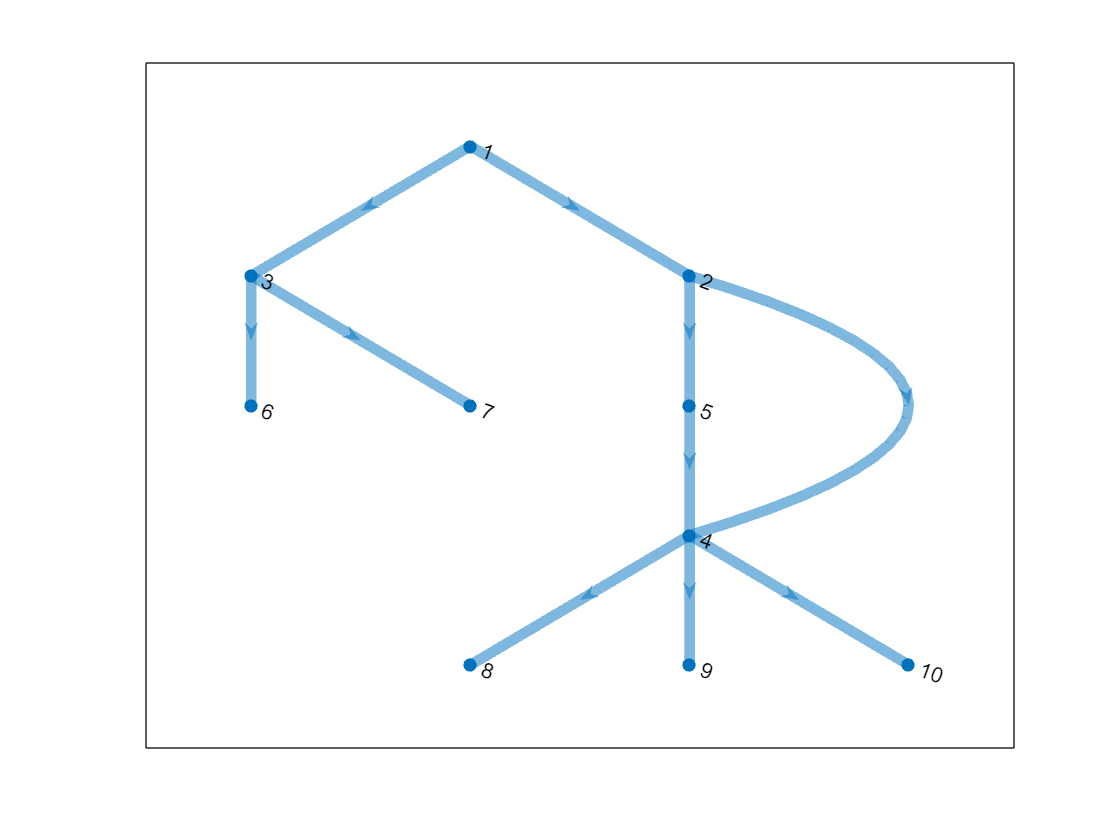

figure
h = plot(G,'LineWidth',4,'Layout','layered');

if ~isDiGraph
    if isa(A,'digraph') || isa(A,'graph')
        A = adjacency(A);
    end
    A = (A+A.')/2;
end
[U,Q,C,D,L,Lmd,Sgm] = fcn_digraphops(A)

U =     0.2531   -0.0136   -0.0000    0.0000   -0.0000    0.5340   -0.6691    0.0443    0.4458   -0.0475
    0.1507    0.1399   -0.0000    0.0000   -0.0000    0.4741    0.0484   -0.6651   -0.4861    0.2281
    0.3839   -0.1673   -0.0000    0.0000   -0.0000    0.0710   -0.2010    0.5793   -0.6659    0.0141
    0.1405    0.2829   -0.0000    0.0000   -0.0000    0.0788    0.0996   -0.0864   -0.1066   -0.9302
    0.1379    0.2101   -0.0000    0.0000   -0.0000    0.5416    0.6489    0.3884    0.2294    0.1378
    0.5502   -0.2798   -0.2952   -0.0706   -0.6386   -0.1805    0.1695   -0.1730    0.1665   -0.0022
    0.5502   -0.2798    0.2952    0.0706    0.6386   -0.1805    0.1695   -0.1730    0.1665   -0.0022
    0.2014    0.4731    0.7306   -0.1785   -0.3180   -0.2003   -0.0840    0.0258    0.0267    0.1429
    0.2014    0.4731   -0.2532    0.7756    0.0313   -0.2003   -0.0840    0.0258    0.0267    0.1429
    0.2014    0.4731   -0.4774   -0.5972    0.2866   -0.2003   -0.0840    0.0258    0.0

Q =    -0.3512   -0.0102   -0.5906    0.0533    0.3900    0.1411
   -0.0185    0.6376    0.0133    0.1472    0.2571   -0.7108
   -0.0063    0.2176    0.0816    0.9031   -0.1228    0.3395
    0.8138   -0.3069   -0.2968    0.2041    0.3018   -0.1506
    0.3878    0.3418   -0.0320   -0.1744   -0.5884    0.0470
    0.0893    0.0026    0.5078   -0.0459    0.3566    0.1290
    0.0893    0.0026    0.5078   -0.0459    0.3566    0.1290
   -0.1260   -0.3342    0.1147    0.1669   -0.1582   -0.3170
   -0.1260   -0.3342    0.1147    0.1669   -0.1582   -0.3170
   -0.1260   -0.3342    0.1147    0.1669   -0.1582   -0.3170


C =    0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.5000 + 0.5000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   

D =     1.4142         0         0         0         0         0         0         0         0         0
         0    2.1213         0         0         0         0         0         0         0         0
         0         0    2.1213         0         0         0         0         0         0         0
         0         0         0    3.5355         0         0         0         0         0         0
         0         0         0         0    1.4142         0         0         0         0         0
         0         0         0         0         0    0.7071         0         0         0         0
         0         0         0         0         0         0    0.7071         0         0         0
         0         0         0         0         0         0         0    0.7071         0         0
         0         0         0         0         0         0         0         0    0.7071         0
         0         0         0         0         0         0         0         0       

L =    1.4142 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   2.1213 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   0.0000 + 0.0000i   2.1213 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   3.5355 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i  -0.5000 - 0.5000i   1.4142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -

Lmd =     0.3583         0         0         0         0         0         0         0         0         0
         0    0.4081         0         0         0         0         0         0         0         0
         0         0    0.7071         0         0         0         0         0         0         0
         0         0         0    0.7071         0         0         0         0         0         0
         0         0         0         0    0.7071         0         0         0         0         0
         0         0         0         0         0    0.9038         0         0         0         0
         0         0         0         0         0         0    1.3002         0         0         0
         0         0         0         0         0         0         0    2.3817         0         0
         0         0         0         0         0         0         0         0    2.7062         0
         0         0         0         0         0         0         0         0     

Sgm =          0    1.2177         0         0         0         0
   -1.2177         0         0         0         0         0
         0         0         0    0.8892         0         0
         0         0   -0.8892         0         0         0
         0         0         0         0         0    0.4760
         0         0         0         0   -0.4760         0


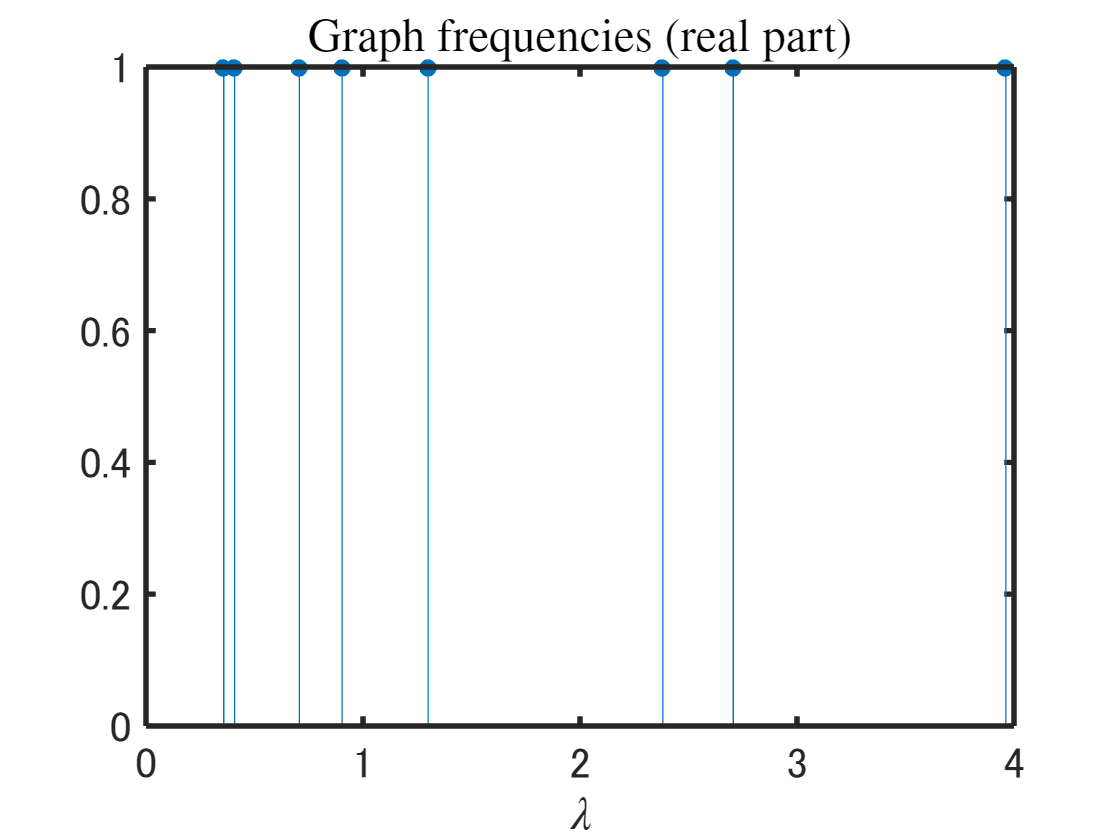

y = ones(1,size(Lmd,2));
stem(diag(Lmd),y,'filled')
title('Graph frequencies (real part)','Interpreter','latex')
xlabel('$\lambda$','Interpreter','latex')

ax = gca;
ax.LineWidth = 2;
ax.FontSize = 16;
exportgraphics(ax,RESULTS_DIR+"EigenValues_sym"+FIGEXT)

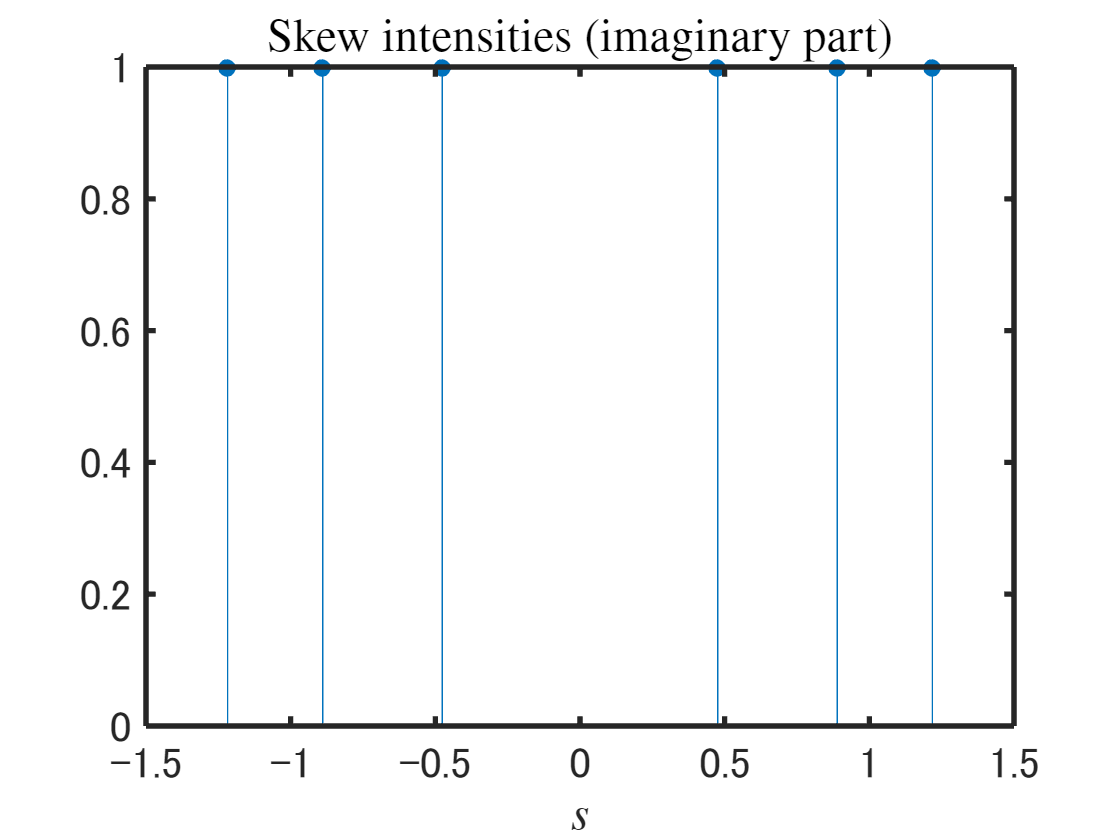

sgm = sort([diag(Sgm,1);diag(Sgm,-1)],'ascend');
idxg = find(sgm);
gma = sgm(idxg);
if ~isempty(gma)
    y = ones(1,length(gma));
    stem(gma,y,'filled')
    title('Skew intensities (imaginary part)','Interpreter','latex')
    xlabel('$s$','Interpreter','latex')

    ax = gca;
    ax.LineWidth = 2;
    ax.FontSize = 16;
    %exportgraphics(ax,RESULTS_DIR+"EigenValues_skw"+FIGEXT)
end

## $\;{\mathbf{u}}_{\lambda_k }$拡張GFT（対称成分）の基底ベクトル

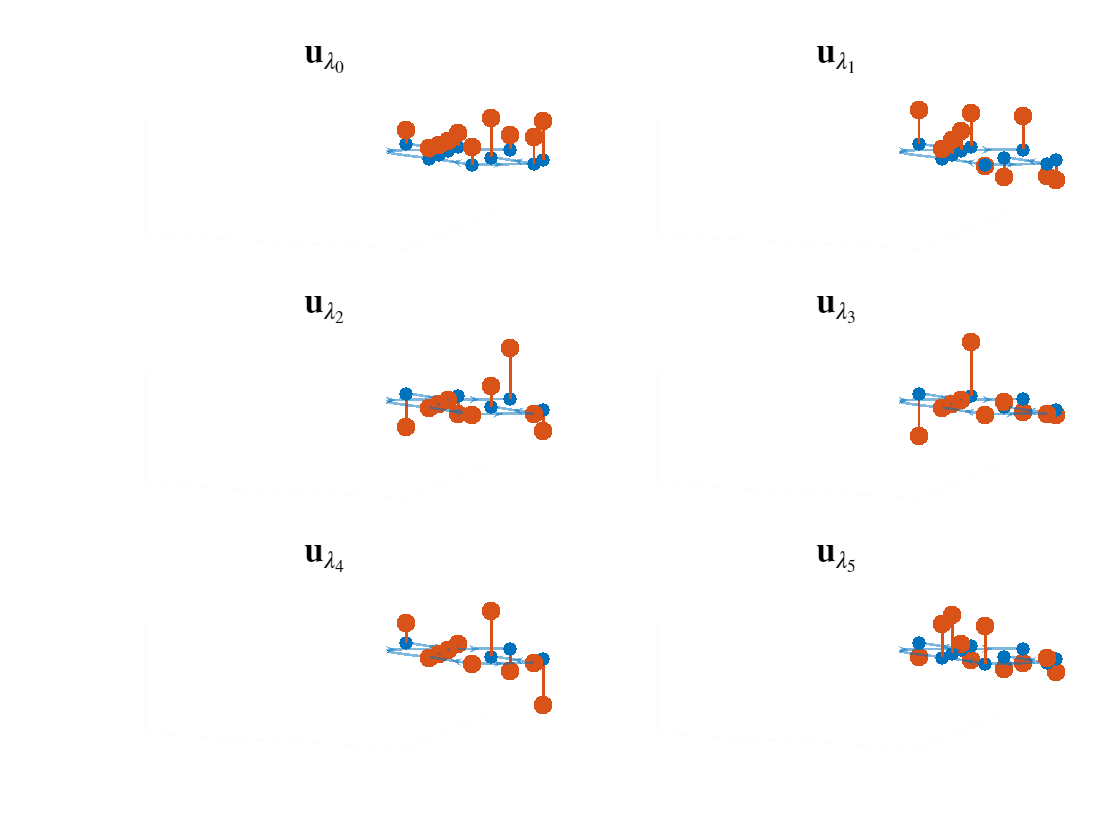

zscale = .8;
fontSize = 12; %36;
lineWidth = 1; %3;
arrowSize = 4; %12;
az = 200;
el = 20;
figure
tiledlayout(3,2)
for k = 0:5
    %figure
    nexttile
    %uk = U(:,k+1)*Lmd(k+1,k+1);
    uk = U(:,k+1);
    %
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,uk,'fill','LineWidth',lineWidth);
    %zlim(zscale*[-1 1])
    %axis off
    title("$\mathbf{u}_{\lambda_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"u"+num2str(k)+FIGEXT)
end

## $\;{\mathit{\mathbf{q}}}_{s_k }$拡張GFT（交代成分）の基底ベクトル

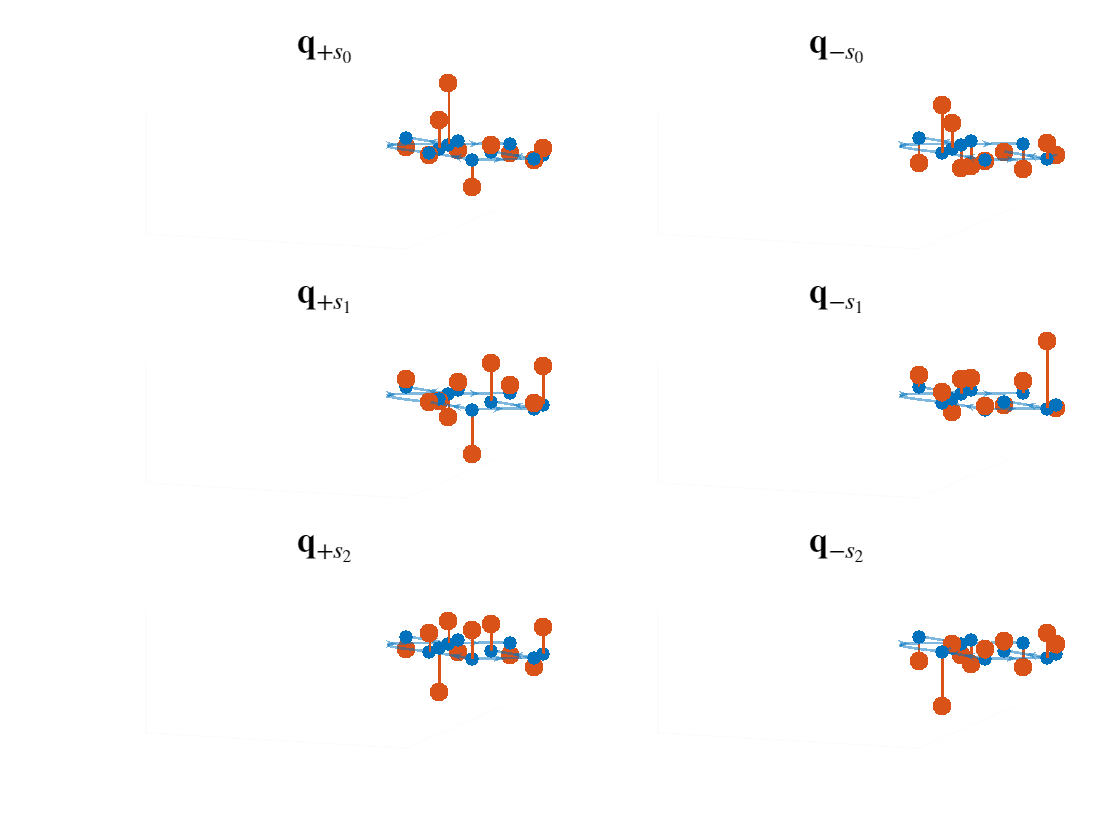

figure
tiledlayout(3,2)
for k = 0:min(5,length(gma)/2-1)
    %figure
    nexttile
    qkp = Q(:,2*k+1);
    % +sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkp,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{+s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qp"+num2str(k)+FIGEXT)
    %
    %figure
    nexttile
    qkm = Q(:,2*k+2);
    % -sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkm,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{-s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qm"+num2str(k)+FIGEXT)
end

## 
$$\;$$


## 変動の確認


$$\mathbf{L}=\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)$$



$$\underbrace{\left(\begin{array}{c}
y_{1}\\
y_{2}\\
y_{3}\\
y_{4}
\end{array}\right)}_{\mathbf{y}}=\underbrace{\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)}_{\mathbf{L}}\underbrace{\left(\begin{array}{c}
x_{1}\\
x_{2}\\
x_{3}\\
x_{4}
\end{array}\right)}_{\mathbf{x}}$$



$$d_{k,k}:=\sum_{\ell\in\mathcal{N}\backslash \{k\}} |c_{k,\ell}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  |c_{\ell,k}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}b_{\ell,k}}=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}\bar{c}_{k,\ell}}

$$


ただし， $\mathcal{N}:=\{1,2,\cdots,N\}$。


$$y_{k}=d_{k,k}x_k-\sum_{\ell=k+1}^{N} b_{k,\ell}x_\ell-\sum_{\ell=1}^{k-1} \bar{b}_{k,\ell}x_\ell$$



$$\Delta_{\mathbf{L}}(\mathbf{x})=\mathbf{x}^T\mathbf{L}\mathbf{x}=\sum_{k\in\mathcal{N}}\sum_{\ell=k+1}^N |b_{k,\ell}|\cdot|x_k-e^{-j\angle b_{k,\ell}} x_\ell|^2$$


行列計算

nDims = size(L,1);
x = randn(nDims,1);
xLx = x.'*L*x

xLx = 12.6043 - 0.0000i

累積加算

tv = 0;
for iRow = 1:nDims
    xk = x(iRow);
    for iCol = iRow+1:nDims
        ckl = C(iRow,iCol);
        xl = x(iCol);
        tv = tv + abs(ckl)*abs(xk-exp(1j*angle(ckl))*xl)^2;
    end
end
tv

tv = 12.6043

誤差評価

assert(abs(xLx - tv)<1e-6,'Invalid TV')

waterlevel = randn(nDims)

waterlevel =    -0.1539   -0.5342    0.0006    0.1812    1.5239   -0.9510    0.2775   -0.2385   -0.5160   -0.3918
   -0.2752    0.2426   -0.7562    0.0543    0.5458    0.7948    0.0870   -0.4840   -1.0851   -1.4847
    0.2411   -0.1006    0.4043    0.6878    2.0099    0.0714    0.1736   -0.3273   -0.7072   -0.3446
    0.7547   -1.6250   -0.7939   -1.3934    1.4167   -0.7737    0.4536    0.4755   -0.3017   -1.3239
   -0.2919   -1.5144    0.8598    1.4254    0.0115    0.7742   -0.6035   -0.1300   -1.2004   -0.5748
    0.4584    1.0262    0.0669   -0.8939   -0.9390    0.2657   -0.7970   -0.5944   -0.0194   -0.7407
    1.7553   -0.7581   -1.6394    0.0378   -1.7389   -0.2351    0.3606   -0.4438    0.3404   -1.1850
    0.9315    2.0783   -2.4247   -0.3636    0.0170    1.8773    1.8851   -1.3225   -0.9632   -2.0649
    0.8253   -2.2220   -0.2838    0.1496    0.2192    0.6092   -0.3068   -0.8595    1.1139    0.5651
   -0.8148    0.4488    1.1458   -1.9445    1.0458   -0.1103   -1.0127   -1.41

## AuGFTによるフィルタ処理

パラメータ $\alpha$ を導入し一般化したAuGFT

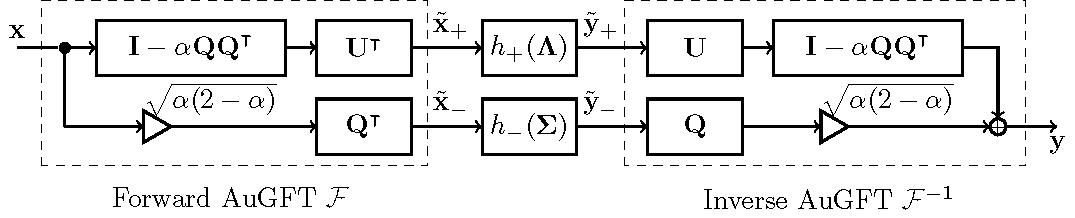

- 
$$0\leq \alpha \leq 1$$


- 
$$\beta = \sqrt{\alpha(2-\alpha)$$


syms alpha beta
eqn1 = alpha == (1-sqrt(1-beta^2));
eqn2 = beta <= 1;
eqn3 = beta >= 0;
eqn4 = alpha <= 1;
eqn5 = alpha >= 0;
eqns = [eqn1; eqn2; eqn3; eqn4; eqn5]

$$eqns = \left(\begin{array}{c} \alpha =1-\sqrt{1-\beta^{2}}\\ \beta \leq 1\\ 0\leq \beta \\ \alpha \leq 1\\ 0\leq \alpha \end{array}\right)$$

res = solve(eqns,beta,'ReturnConditions',true)

res = フィールドをもつ struct :
          beta: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


res.beta

$$ans = \left(\begin{array}{c} 0\\ \sqrt{-\alpha \,\left(\alpha -2\right)} \end{array}\right)$$

res.conditions

$$ans = \left(\begin{array}{c} \alpha =0\\ 0<\alpha \wedge \alpha <1 \end{array}\right)$$

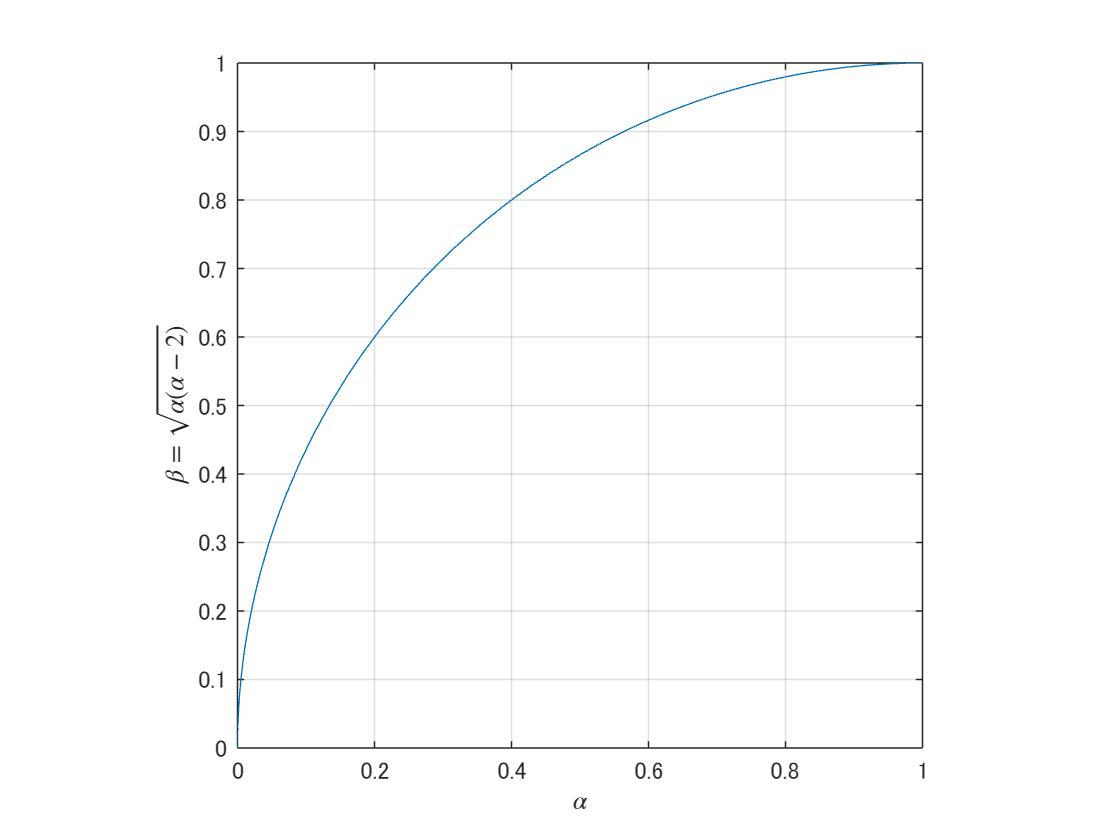

figure
fplot(@(x) sqrt(x.*(2-x)),[0 1])
xlabel('$\alpha$','Interpreter','latex')
ylabel('$\beta=\sqrt{\alpha(\alpha-2)}$','Interpreter','latex')
axis equal
grid on

x = waterlevel;
freqXSet = fcn_fwdAuGFT(x,U,Q)

freqXSet =     1.1656   -0.4726   -0.8529   -0.3607    0.2327    0.3572   -0.0390   -1.3107   -0.8668   -1.3957
   -0.0303   -0.5330   -0.3833   -0.6789    1.0705    0.8539    0.2477   -1.0123   -0.8831    0.0248
    1.2434    1.3399   -2.7503    0.8998   -0.7785    1.1220    2.2801   -0.0296   -0.1223   -2.7375
    1.0519   -2.4882   -0.5921    1.4078   -0.5140    0.1681    0.1121    0.4238    2.0084   -0.4190
    0.3243   -1.7414    0.0009    0.1579   -0.2096   -0.9293   -0.1600    0.0848    0.1163    0.9639
   -0.5540   -1.0036    0.4421    1.0373    1.1477   -0.1309   -0.1131    0.1998   -1.0544   -0.9085
    0.1643   -0.5323    0.1563    0.4030   -1.2757    0.6345   -0.4862    0.1917   -0.1546   -0.4459
   -0.1277   -0.5694    0.9565    0.8173    0.9004   -0.0562   -0.1014    0.0212   -0.2323    0.6604
    0.1943   -0.4530    0.0143   -0.0495   -0.9937   -0.3178   -0.2289   -0.1889    0.1994    0.1800
   -0.4466    0.9646    0.3218    0.8591   -0.7254    1.0002   -0.3014   -0.8101

y = fcn_invAuGFT(freqXSet,U,Q)

y =    -0.1539   -0.5342    0.0006    0.1812    1.5239   -0.9510    0.2775   -0.2385   -0.5160   -0.3918
   -0.2752    0.2426   -0.7562    0.0543    0.5458    0.7948    0.0870   -0.4840   -1.0851   -1.4847
    0.2411   -0.1006    0.4043    0.6878    2.0099    0.0714    0.1736   -0.3273   -0.7072   -0.3446
    0.7547   -1.6250   -0.7939   -1.3934    1.4167   -0.7737    0.4536    0.4755   -0.3017   -1.3239
   -0.2919   -1.5144    0.8598    1.4254    0.0115    0.7742   -0.6035   -0.1300   -1.2004   -0.5748
    0.4584    1.0262    0.0669   -0.8939   -0.9390    0.2657   -0.7970   -0.5944   -0.0194   -0.7407
    1.7553   -0.7581   -1.6394    0.0378   -1.7389   -0.2351    0.3606   -0.4438    0.3404   -1.1850
    0.9315    2.0783   -2.4247   -0.3636    0.0170    1.8773    1.8851   -1.3225   -0.9632   -2.0649
    0.8253   -2.2220   -0.2838    0.1496    0.2192    0.6092   -0.3068   -0.8595    1.1139    0.5651
   -0.8148    0.4488    1.1458   -1.9445    1.0458   -0.1103   -1.0127   -1.4130   -1.5

rmse = @(rx,ry) norm(rx(:)-ry(:),2)/sqrt(numel(rx));
rmse(waterlevel,y)

ans = 4.6019e-16

assert(norm(x(:)-y(:))<1e-6)

## 辞書学習問題設定

### 問題設定

    
$$\{\hat{\mathbf{G}},\hat{\mathbf{X}}\}=\arg\min_{\{\mathbf{G},\mathbf{X}\}}\frac{1}{2}\|\mathbf{V}-\mathbf{GX}\|_\mathrm{F}^2+{\beta}\mathcal{R}(\mathbf{X})$$


ただし， $\mathbf{V} = (\mathbf{v}_k)\in\mathbb{R}^{N\times K}$ は観測グラフ信号，$\beta$ は正則化パラメータ， $\mathbf{G}=(\mathbf{H}_0,\cdots,\mathbf{H}_{P-1})\in\mathbb{R}^{N\times PN}$ は合成辞書行列，$\mathbf{X}\in\mathbb{R}^{PN\times K}$ は係数行列，$N$はノード数， $K$は観測数，$P $はフィルタ数

       
$$\mathbf{x}_k := [\mathbf{X}]_{:,k}\in\mathbb{R}^{PN}$$


    
$$\mathcal{R}(\mathbf{X}) =\sum_{k}\|\mathbf{x}_k\|_1$$


    
$$\mathbf{x}_k := [\mathbf{X}]_{:,k}$$


### 係数更新ステップ

    
$$\hat{\mathbf{X}}=\arg\min_{\mathbf{X}}\frac{1}{2}\|\mathbf{V}-\hat{\mathbf{G}}\mathbf{X}\|_\mathrm{F}^2+{\beta}\mathcal{R}(\mathbf{X})$$


    
$$\Leftrightarrow \hat{\mathbf{x}}_k=\arg\min_{\mathbf{x}_k}\frac{1}{2}\|\mathbf{v}_k-\hat{\mathbf{G}}\mathbf{x}_k\|_2^2+{\beta}\|\mathbf{x}_k\|_1$$


     $\therefore$ ISTAで解く

### 辞書更新ステップ

    
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2}\|\mathbf{V}-\mathbf{G}_{\mathbf{\theta}}\hat{\mathbf{X}}\|_\mathrm{F}^2$$


    
$$\hat{\mathbf{G}}=\mathbf{G}_{\hat{\mathbf{\theta}}}$$


%x_in = waterlevel

### 自作関数:グラフ信号の可視化

function mygstem3(G, y, RESULTS_DIR, yfile,FIGEXT)
zscale = 400;
fontSize = 36;
lineWidth = 3;
arrowSize = 12;
az = 200;
el = 20;
%
figure
p1 = plot(G,'LineWidth',lineWidth);
p1.ArrowSize = arrowSize;
p1.NodeLabel = {};
hold on
stem3(p1.XData,p1.YData,y,'fill','LineWidth',lineWidth);
axis off
view(az,el)
hold off
ax = gca;
%
ax.FontSize = fontSize;
ax.ZLim = zscale*[-1 1];
ax.Box = 'on';
ax.XColor = .99*[1 1 1];
ax.YColor = .99*[1 1 1];
ax.ZColor = .99*[1 1 1];
ax.XLim = [2 7];
ax.YLim = [2 12];
ax.Clipping = 'off';
%
%exportgraphics(ax,RESULTS_DIR+yfile+FIGEXT)
end

function cost =  mycost_(hp,hm,U,Q,L,x)
y = myfilt_(x,hp,hm,U,Q);
v = L*y;
cost = 0;
for idx = 1:size(v,2)
    cost = cost + real(y(:,idx)'*v(:,idx));
end
cost = cost/size(v,2);
end

function y = myfilt_(x,hp,hm,U,Q)
N = size(x,1);
r = size(Q,2);
freqX = fcn_fwdAuGFT(x,U,Q);
freqXp = freqX(1:N,:);
freqYp = hp.*freqXp;
freqXm = freqX(N+1:end,:);
%
if r == 0
    freqYm = [];
else
    tmp = [1 0 ; -1 0]*ones(2,r/2)*diag(hm); % FIXME: h_(Σ)
    tmp = upsample(tmp.',2).';
    tmp = tmp(:,1:end-1);
    h_Sgm = diag(tmp(1,:),1)+diag(tmp(2,:),-1);
    freqYm = h_Sgm * freqXm; % TODO: h_Sgm
end
%
freqY = vertcat(freqYp,freqYm);
y = fcn_invAuGFT(freqY,U,Q);

end

## 辞書学習問題設定（付録）

### 問題設定

    
$$\{\hat{\mathbf{G}},\hat{\mathbf{X}}\}=\arg\min_{\{\mathbf{G},\mathbf{X}\}}\frac{1}{2}\|\mathbf{V}-\mathbf{GX}\|_\mathrm{F}^2+{\beta}\mathcal{R}(\mathbf{X})$$


ただし， $\mathbf{V} = (\mathbf{v}_k)$ は観測グラフ信号，$\beta$ は正則化パラメータ，

    
$$\mathcal{R}(\mathbf{X}) = \frac{1}{2}\sum_{k}\Delta_{\mathbf{L}}(\mathbf{Gx}_k)=\frac{1}{2}\sum_{k}(\mathbf{Gx}_k)^{\mathtt{T}}\mathbf{L}\mathbf{Gx}_k$$


    
$$\mathbf{x}_k := [\mathbf{X}]_{:,k}$$


### 係数更新ステップ

    
$$\hat{\mathbf{X}}=\arg\min_{\mathbf{X}}\frac{1}{2}\|\mathbf{V}-\hat{\mathbf{G}}\mathbf{X}\|_\mathrm{F}^2+{\beta}\mathcal{R}(\mathbf{X})$$


    
$$\Leftrightarrow \hat{\mathbf{x}}_k=\arg\min_{\mathbf{x}_k}\frac{1}{2}\|\mathbf{v}_k-\hat{\mathbf{G}}\mathbf{x}_k\|_2^2+\frac{\beta}{2} (\hat{\mathbf{G}}\mathbf{x}_k)^{\mathtt{T}}\mathbf{L}\hat{\mathbf{G}}\mathbf{x}_k$$


 $\mathbf{z}$ が複素ベクトル，$\mathbf{L}$がエルミート対称（複素）行列であることに注意． 

     
$$\frac{1}{2}\frac{\partial}{\partial \mathbf{z}^{\mathtt{H}}}
\left(\|\mathbf{v}-\mathbf{G}\mathbf{z}\|_2^2+\beta (\mathbf{Gz})^{\mathtt{H}}\mathbf{L}\mathbf{Gz}\right)
$$


    
$$=\frac{1}{2}\frac{\partial}{\partial \mathbf{z}^{\mathtt{H}}}\|\mathbf{v}-\mathbf{G}\mathbf{z}\|_2^2+\beta (\mathbf{Gz})^{\mathtt{H}}\mathbf{L}\mathbf{Gz}
$$


    
$$=-\mathbf{G}^\mathtt{H}(\mathbf{v}-\mathbf{G}\mathbf{z})+\beta \mathbf{G}^\mathtt{H}\mathbf{L}\mathbf{Gz}$$


    
$$=-\mathbf{G}^\mathtt{H}\mathbf{v}+\mathbf{G}^\mathtt{H}(\mathbf{I}+\beta \mathbf{L})\mathbf{Gz}=\mathbf{0}$$


    
$$\therefore \hat{\mathbf{x}}=\left(\mathbf{G}^\mathtt{T}(\mathbf{I}+\beta \mathbf{L})\mathbf{G}\right)^{-1}\mathbf{G}^\mathtt{T}\mathbf{v}$$
  

### 辞書更新ステップ

    
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2}\|\mathbf{V}-\mathbf{G}_{\mathbf{\theta}}\hat{\mathbf{X}}\|_\mathrm{F}^2$$


    
$$\hat{\mathbf{G}}=\mathbf{G}_{\hat{\mathbf{\theta}}}$$
